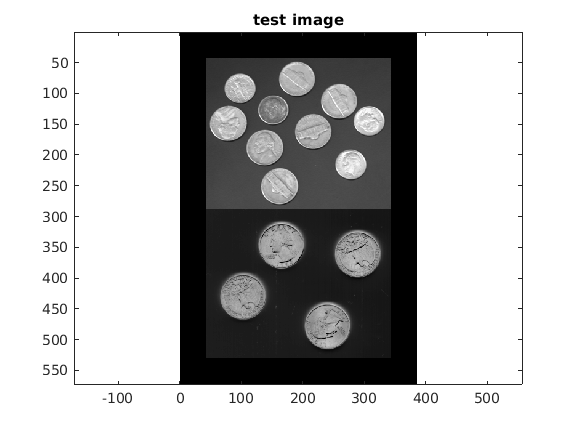

% Define the filter size we will use in step 2:
filtsize = 85;

% Creating test image 'im' by splicing together two built in images.
% Also zero-padding (adding zeros around the border) with half the 
% filter size (filtsize) we will use so that the filter could be 
% centered on any actual image pixel, including those near the border.
% 'coins.png' contains bright nickels and dimes on a dark background
% 'eight.tif' contains dark quarters on a bright background, so we invert it
% to match 'coins.png'
im1 = imread('coins.png');
[r,c] = size(im1);
im2 = imread('eight.tif');
[r2,c2] = size(im2);
filtsizeh = floor(filtsize/2);
im = zeros(r+r2+filtsize,c+filtsize);
im(filtsizeh+1:filtsizeh+r+r2,filtsizeh+1:filtsizeh+c) = [im1;255-im2(:,1:c)];
[r,c] = size(im);
imagesc(im);colormap(gray);title('test image');axis equal;

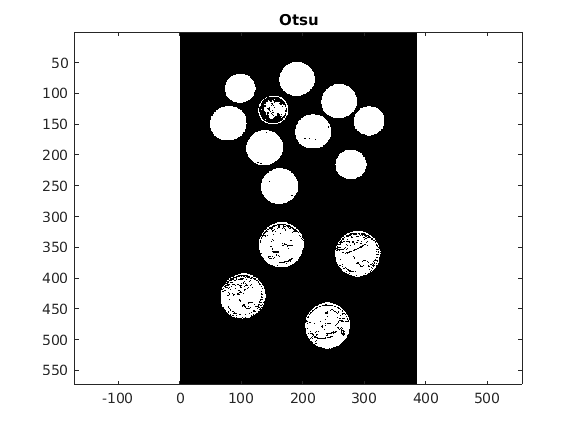


% Initializing assessed/displayed variables as empty so that code is executable 
msk=[]; msk_dil=[]; msk_dil_erd=[]; centroid=[]; component_size=[]; 

%%%%% 1. Localize the centroid of each coin
% Otsu threshold
msk = OtsuThreshold(im);
figure; imagesc(msk); colormap(gray); title('Otsu'); axis equal;

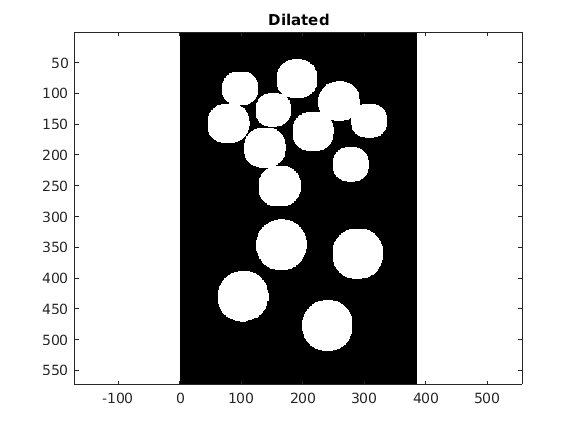


% Dilate 9x9
msk_dil = imdilate(msk,ones(9,9));
figure; imagesc(msk_dil); colormap(gray); title('Dilated'); axis equal;

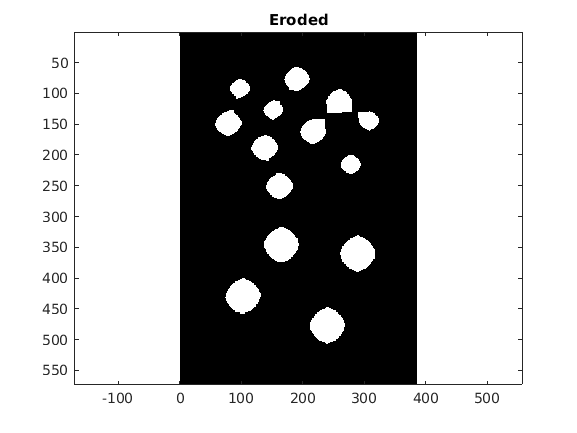


% Erode 23x23
msk_dil_erd = imerode(msk_dil,ones(23,23));
figure; imagesc(msk_dil_erd); colormap(gray); title('Eroded'); axis equal;

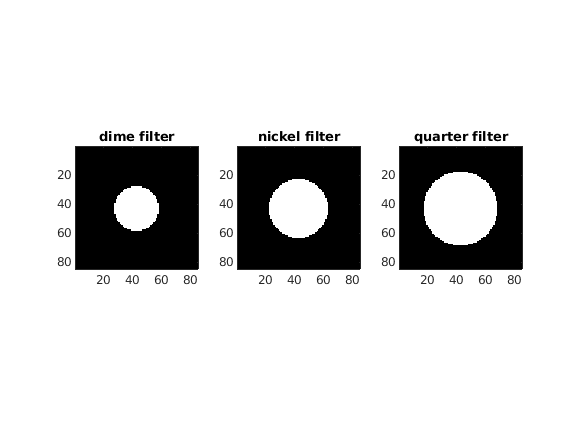



% Connected components to get centroids of coins:
cc = bwconncomp(msk_dil_erd);
props_struct = regionprops(cc);
centroid = zeros(length(props_struct),2);
component_size = zeros(length(props_struct),1);
for i=1:length(props_struct)
    centroid(i,:) = round(props_struct(i).Centroid);
    component_size(i) = props_struct(i).Area;
end


%%%%% 2. Measure features for each coin using a bank of matching filters
% make matching filters to create features
% Define diameters to use for filters
dimediameter = 31;
quarterdiameter = 51;
nickeldiameter = 41;

% Initialize assessed variable D
D=[]; nickelfilter = []; dimefilter = []; quarterfilter = [];

% Use the MakeCircleMatchingFilter function to create matching filters for dimes, nickels, and quarters
% (This is in a separate Matlab grader problem. Save your work, 
%       complete the corresponding grader problem and embed the solution 
%       in the helper function list below.)
nickelfilter = MakeCircleMatchingFilter(nickeldiameter,filtsize);
dimefilter = MakeCircleMatchingFilter(dimediameter,filtsize);
quarterfilter = MakeCircleMatchingFilter(quarterdiameter,filtsize);

figure;
subplot(1,3,1); imagesc(dimefilter); colormap(gray); title('dime filter'); axis tight equal;
subplot(1,3,2); imagesc(nickelfilter); colormap(gray); title('nickel filter'); axis tight equal;
subplot(1,3,3); imagesc(quarterfilter); colormap(gray); title('quarter filter'); axis tight equal;


% Evaluate each of the 3 matching filters on each coin to serve as 3 feature measurements 
D = zeros(length(centroid),3);
for i=1:length(centroid)
    D(i,1) = corr(dimefilter(:),reshape(msk_dil_erd(centroid(i,2)-filtsizeh:...
        centroid(i,2)+filtsizeh,centroid(i,1)-filtsizeh:centroid(i,1)+filtsizeh),[filtsize*filtsize,1]));
    D(i,2) = corr(nickelfilter(:),reshape(msk_dil_erd(centroid(i,2)-filtsizeh:...
        centroid(i,2)+filtsizeh,centroid(i,1)-filtsizeh:centroid(i,1)+filtsizeh),[filtsize*filtsize,1]));
    D(i,3) = corr(quarterfilter(:),reshape(msk_dil_erd(centroid(i,2)-filtsizeh:...
        centroid(i,2)+filtsizeh,centroid(i,1)-filtsizeh:centroid(i,1)+filtsizeh),[filtsize*filtsize,1]));    
end

figure;
subplot(1,3,1); imagesc(dimefilter); colormap(gray); title('dime filter'); axis tight equal;
subplot(1,3,2); imagesc(nickelfilter); colormap(gray); title('nickel filter'); axis tight equal;
subplot(1,3,3); imagesc(quarterfilter); colormap(gray); title('quarter filter'); axis tight equal;


%%%%% 3. Perform k-means clustering of features for unsupervised learning classifier
rng(0);
cls_init=[]; cls=[]; totcount=[];
cls_init = kmeans(D,3);

cls_init

cls_init =      3
     1
     2
     3
     2
     1
     3
     3
     3
     1


% relabel centroid classes based on average size of the objects in each class. smallest will be dime, next nickel, and largest quarter
class_ave_object_size = zeros([3,1]);
class_ave_object_size(1) = mean(component_size(cls_init==2),'all');
class_ave_object_size(2) = mean(component_size(cls_init==1),'all');
class_ave_object_size(3) = mean(component_size(cls_init==3),'all');
[~,classmap] = sort(class_ave_object_size,'ascend');
for i=1:length(cls_init)
    cls(i) = classmap(cls_init(i));
end
cls = 4-cls';
cls

cls =      2
     3
     1
     2
     1
     3
     2
     2
     2
     3


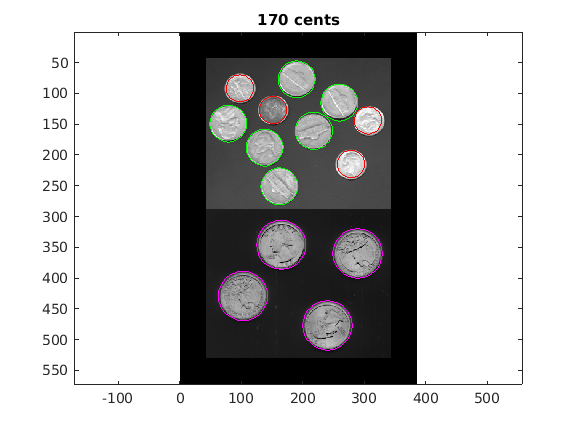

% Visualize the result
figure; imagesc(im);colormap(gray);title('test image');hold on;axis equal;

% plot circles around each coin with different color/diameter unique to each type and count the change
totcount = 0;
for i=1:length(centroid)
    totcount = totcount + AddCoinToPlotAndCount(centroid(i,1),centroid(i,2),cls(i));
end

title([num2str(totcount),' cents'])



%%%%%%%%%%%%%%%%%%%% Helper Functions %%%%%%%%%%%%%%%%%%%%%

function [coinvalue,x_plot,y_plot,col] = AddCoinToPlotAndCount(x,y,cls)
% initialize radians for defining x_plot and y_plot using cos and sin functions
rads = 0:2*pi/32:2*pi;
% initialize parameters for radius and color of circle for each type of coin
coin_r = [22,30,40];
colors = ['r','g','m'];
% use if-elseif statement to define x_plot, y_plot, col
%   when cls is 1, we found a dime
%   when cls is 2, we found a nickel
%   when cls is 3, we found a quarter
switch cls
    case 1
        coinvalue = 10;
        x_plot = coin_r(1)*cos(rads)+x;
        y_plot = coin_r(1)*sin(rads)+y;
        col = colors(1);
    case 2
        coinvalue = 5;
        x_plot = coin_r(2)*cos(rads)+x;
        y_plot = coin_r(2)*sin(rads)+y;
        col = colors(2);
    case 3
        coinvalue = 25;
        x_plot = coin_r(3)*cos(rads)+x;
        y_plot = coin_r(3)*sin(rads)+y;
        col = colors(3);
end
plot(x_plot,y_plot,col);
end

function filter = MakeCircleMatchingFilter(diameter,filtsize)
filter = zeros(filtsize,filtsize);
radius = diameter/2;
c = (filtsize+1)/2;
for i=1:filtsize
    for j=1:filtsize
        if (i-c)*(i-c) + (j-c)*(j-c) <= radius*radius
            filter(i,j) = 1;
        end
    end
end
end

function [msk,thrsh] = OtsuThreshold(im)
hst = imhist(im);
res = otsuthresh(hst);
thrsh = res*255;
msk = im>thrsh;
end
